# Part 1 Spectral model

## 1.1 Plot Spectral Sensitivty Functions

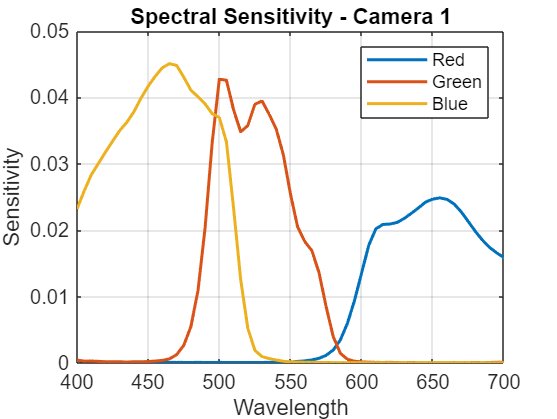

% Load data for spectral sensitivity functions and wavelengths
load('Ad.mat'); % Spectral sensitivity for Camera 1
load('Ad2.mat'); % Spectral sensitivity for Camera 2
load('illum.mat'); % Wavelength range

% Plot sensitivity functions for both cameras
figure;
plot(waverange, Ad, 'LineWidth', 1.5);
title('Spectral Sensitivity - Camera 1');
xlabel('Wavelength');
ylabel('Sensitivity');
legend('Red', 'Green', 'Blue');
grid on;

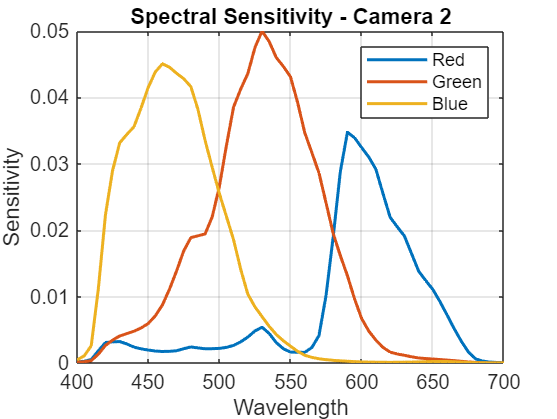


figure;
plot(waverange, Ad2, 'LineWidth', 1.5);
title('Spectral Sensitivity - Camera 2');
xlabel('Wavelength');
ylabel('Sensitivity');
legend('Red', 'Green', 'Blue');
grid on;

## 1.2 Compute raw RGB outputs

% Load data
load('chips20.mat'); % Spectral reflectance data for 20 objects
load('illum.mat'); % Illuminants, one vector per lumminant
load('Ad.mat'); % Spectral sensitivity for Camera 1
load('Ad2.mat'); % Spectral sensitivity for Camera 2

% D65 as the current illuminant
illuminant = CIED65;

% Compute RGB raw outputs for Camera 1
RGB_raw_D65_cam1 = chips20 .* illuminant;
RGB_raw_D65_cam1 = RGB_raw_D65_cam1 * Ad;

% Compute RGB raw outputs for Camera 2
RGB_raw_D65_cam2 = chips20 .* illuminant;
RGB_raw_D65_cam2 = RGB_raw_D65_cam2 * Ad2;

% Display the results
disp('RGB Raw Outputs for Camera 1 under D65:');

RGB Raw Outputs for Camera 1 under D65:


disp(RGB_raw_D65_cam1);

    0.2979    0.3654    0.5056
    0.1397    0.1277    0.2314
    0.0408    0.0651    0.1183
    0.0711    0.0977    0.1715
    0.1003    0.3576    0.4496
    0.1137    0.2291    0.3414
    0.2697    0.2824    0.1179
    0.0345    0.0318    0.0527
    0.1561    0.1547    0.0481
    0.0201    0.0248    0.0368
    0.0972    0.0467    0.1289
    0.1110    0.0672    0.0886
    0.0737    0.0517    0.0931
    0.0584    0.1327    0.0656
    0.1226    0.2596    0.5293
    0.0787    0.0537    0.1410
    0.0700    0.2887    0.4728
    0.1151    0.0602    0.0561
    0.2861    0.3616    0.1974
    0.1512    0.2132    0.3133



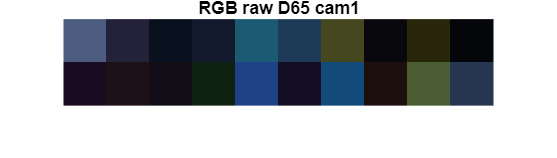


% Show colors RGB_raw_D65_cam1
figure;
showRGB(RGB_raw_D65_cam1);
title('RGB raw D65 cam1');


disp('RGB Raw Outputs for Camera 2 under D65:');

RGB Raw Outputs for Camera 2 under D65:


disp(RGB_raw_D65_cam2);

    0.3125    0.5787    0.4609
    0.1413    0.2131    0.2049
    0.0462    0.1010    0.1052
    0.0783    0.1542    0.1527
    0.1557    0.5100    0.4109
    0.1381    0.3442    0.3091
    0.2619    0.4339    0.1244
    0.0354    0.0523    0.0471
    0.1689    0.2683    0.0561
    0.0216    0.0392    0.0331
    0.0769    0.0815    0.1111
    0.1082    0.1220    0.0799
    0.0704    0.0875    0.0824
    0.0805    0.2098    0.0684
    0.1458    0.3915    0.4734
    0.0686    0.0906    0.1223
    0.1078    0.4063    0.4297
    0.1088    0.1117    0.0527
    0.2935    0.5418    0.1978
    0.1666    0.3336    0.2829



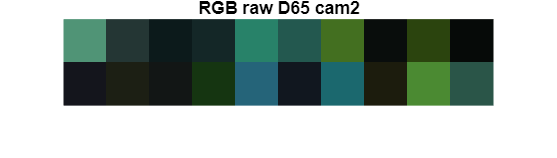


% Show colors RGB_raw_D65_cam2
figure;
showRGB(RGB_raw_D65_cam2);
title('RGB raw D65 cam2');

# Part 2 Calibration input devices

## 2.1 Compute Normalization Factors

% Define a white spectrum (ones for all wavelengths)
white_spectrum = ones(1, 61);

% Compute normalization factors for Camera 1
norm_factors_cam1 = white_spectrum * Ad; % Expected vector 1x3

% Compute normalization factors for Camera 2
norm_factors_cam2 = white_spectrum * Ad2; % Expected vector 1x3

disp('Normalization factors for Camera 1:');

Normalization factors for Camera 1:


disp(norm_factors_cam1);

    0.4635    0.5646    0.8585



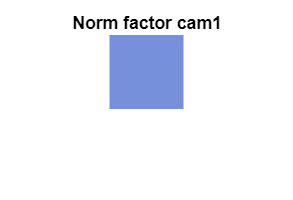


% Show norm color
figure;
showRGB(norm_factors_cam1);
title('Norm factor cam1');


disp('Normalization factors for Camera 2:');

Normalization factors for Camera 2:


disp(norm_factors_cam2);

    0.4726    0.8747    0.7420



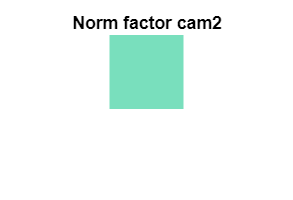


% Show norm color
figure;
showRGB(norm_factors_cam2);
title('Norm factor cam2');

## 2.2 Calibrate Raw RGB

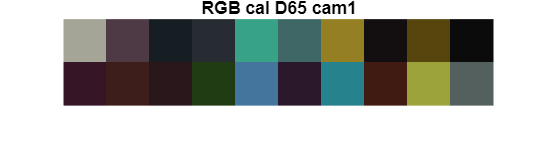

% Normalize raw RGB data using normalization factors for cam1
RGB_cal_D65_cam1 = RGB_raw_D65_cam1 ./ norm_factors_cam1; % Elementwise division

% Show calibrated color
figure;
showRGB(RGB_cal_D65_cam1);
title('RGB cal D65 cam1');

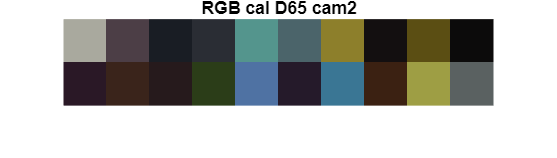


% Normalize raw RGB data using normalization factors for cam2
RGB_cal_D65_cam2 = RGB_raw_D65_cam2 ./ norm_factors_cam2;

% Show norm color
figure;
showRGB(RGB_cal_D65_cam2);
title('RGB cal D65 cam2');

## 2.3 Compare Illuminants D65 and CIEA 

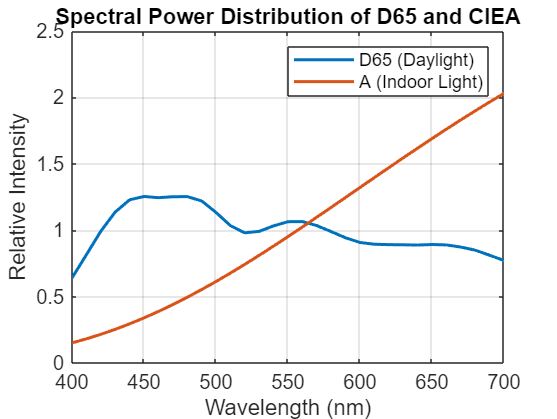

% Compare spectral power distributions of D65 and A
figure;
plot(waverange, CIED65, 'LineWidth', 1.5); hold on;
plot(waverange, CIEA, 'LineWidth', 1.5);
title('Spectral Power Distribution of D65 and CIEA');
xlabel('Wavelength (nm)');
ylabel('Relative Intensity');
legend('D65 (Daylight)', 'A (Indoor Light)');
grid on;

## 2.4 RGB output under CIEA

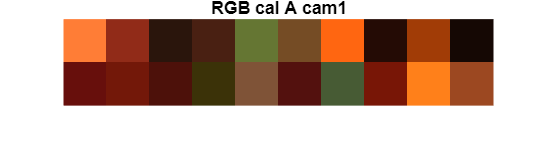

% Compute raw RGB outputs for Camera 1 under Illuminant CIEA (same as prev)
RGB_raw_A_cam1 = chips20 .* CIEA; % Elementwise multiplication
RGB_raw_A_cam1 = RGB_raw_A_cam1 * Ad; % Matrix multiplication

% Calibrate the raw datan(same)
RGB_cal_A_cam1 = RGB_raw_A_cam1 ./ norm_factors_cam1; % Elementwise division

% Show cam1 under CIEA color
figure;
showRGB(RGB_cal_A_cam1);
title('RGB cal A cam1');

## 2.5 White point normalization D65 & CIEA

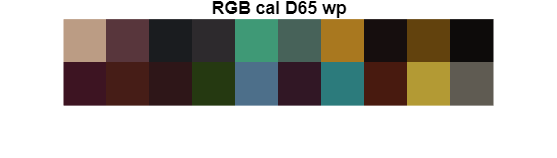

% Compute new normalization factors for D65 and A
norm_factors_D65 = CIED65 * Ad; % gives vector 1x3
norm_factors_CIEA = CIEA * Ad; % gives vector 1x3

% Normalize raw RGB data for D65 and A
RGB_cal_D65_wp = RGB_raw_D65_cam1 ./ norm_factors_D65; % Elementwise division
RGB_cal_CIEA_wp = RGB_raw_A_cam1 ./ norm_factors_CIEA;

% Show cam1 under D65 color
figure;
showRGB(RGB_cal_D65_wp);
title('RGB cal D65 wp');

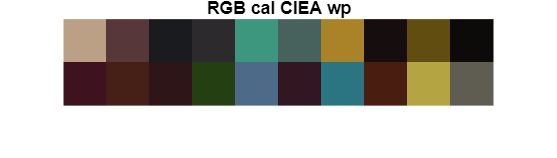


% Show cam1 under CIEA color
figure;
showRGB(RGB_cal_CIEA_wp);
title('RGB cal CIEA wp');

# Part 3 Charactierization

## 3.1 Compute refrence XYZ

% Load color matching functions (CMFs)
load('xyz.mat');

% Compute normalization factor for Y=100 (white reference)
norm_factor = 100 / sum(CIED65 .* xyz(:, 2)'); % eq 7 with cam replacement
disp (norm_factor)

    4.6460




% Compute XYZ reference values for the 20 surfaces under D65
XYZ_D65_ref = norm_factor * (chips20 .* CIED65) * xyz; % eq 8

disp(XYZ_D65_ref)

   66.5076   67.2653   61.0087
   29.1415   25.9561   28.3929
   10.3354   10.4588   14.4753
   17.0944   16.8158   20.9340
   37.2524   49.3000   50.2915
   31.4696   35.3276   40.5003
   51.8681   57.1830   10.0020
    7.1516    6.4429    6.4265
   35.7168   38.2742    5.4609
    4.5704    4.5382    4.4085
   14.7977   10.4425   16.5167
   21.2515   18.0936   10.6582
   13.6952   11.4180   11.4388
   19.1563   25.1057    7.5209
   34.5574   36.1143   65.7332
   13.8335   10.5687   18.0017
   26.8255   34.9493   54.8397
   20.8937   17.7770    6.5922
   59.1042   67.6801   17.7720
   36.1553   37.2942   37.8082



% Show ref under D65 color
% figure;
% howRGB(XYZ_D65_ref);
% title('XYZ D65 ref');

## 3.2 Matrix conversion sRGB

% Load necessary data
load('M_XYZ2RGB.mat'); % Provided sRGB conversion matrix
load('RGB_cal_D65_cam1.mat'); % Calibrated RGB values, Cam 1 under D65
load('XYZ_D65_ref.mat'); % Reference XYZ values for D65

% Convert RGB to XYZ using inverse M_XYZ2RGB, estimation
XYZ_D65_est = (inv(M_XYZ2RGB)*RGB_cal_D65_cam1')';

% Convert estimated XYZ to CIELAB
X_est = XYZ_D65_est(:, 1); % X 
Y_est = XYZ_D65_est(:, 2); % Y
Z_est = XYZ_D65_est(:, 3); % Z
[L_est, a_est, b_est] = xyz2lab(X_est, Y_est, Z_est); % Convert to LAB via xyz2lab

% Convert reference XYZ to LAB for comparison
X_ref = XYZ_D65_ref(:, 1);
Y_ref = XYZ_D65_ref(:, 2);
Z_ref = XYZ_D65_ref(:, 3);
[L_ref, a_ref, b_ref] = xyz2lab(X_ref, Y_ref, Z_ref);

% Compute delata Eab (color difference in LAB space, euclidian)
delta_E = sqrt((L_ref - L_est).^2 + (a_ref - a_est).^2 + (b_ref - b_est).^2);

% Compute mean and max  delta Eab
mean_delta_E = mean(delta_E);
max_delta_E = max(delta_E);

% Display results
disp(mean_delta_E);

   12.6418



disp(max_delta_E);

   31.6232



## 3.3 Compare camera spectral sensitivity

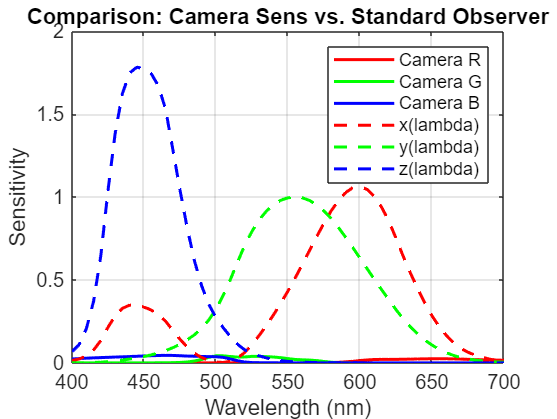

% Load data
load('Ad.mat'); % Spectral sensitivity for cam 1
load('xyz.mat'); % Color matching functions
load('illum.mat'); % Wavelength range

% % Plot Camera 1 sensitivity function (same as before)
% figure;
% plot(waverange, Ad(:, 1), 'r', 'LineWidth', 1.5); hold on;
% plot(waverange, Ad(:, 2), 'g', 'LineWidth', 1.5);
% plot(waverange, Ad(:, 3), 'b', 'LineWidth', 1.5);
% title('Spectral Sensitivity Functions - Camera 1');
% xlabel('Wavelength (nm)');
% ylabel('Sensitivity');
% legend('Red Sensor', 'Green Sensor', 'Blue Sensor');
% grid on;
% 
% % Plot CMFs for standard observer
% figure;
% plot(waverange, xyz(:, 1), 'r', 'LineWidth', 1.5); hold on;
% plot(waverange, xyz(:, 2), 'g', 'LineWidth', 1.5);
% plot(waverange, xyz(:, 3), 'b', 'LineWidth', 1.5);
% title('CIE Color Matching Functions');
% xlabel('Wavelength (nm)');
% ylabel('Sensitivity');
% legend('x(lambda)', 'y(lambda)', 'z(lambda)');
% grid on;

% Combine both plots for comparison
figure;
plot(waverange, Ad(:, 1), 'r', 'LineWidth', 1.5); hold on;
plot(waverange, Ad(:, 2), 'g', 'LineWidth', 1.5);
plot(waverange, Ad(:, 3), 'b', 'LineWidth', 1.5);
plot(waverange, xyz(:, 1), '--r', 'LineWidth', 1.5);
plot(waverange, xyz(:, 2), '--g', 'LineWidth', 1.5);
plot(waverange, xyz(:, 3), '--b', 'LineWidth', 1.5);
title('Comparison: Camera Sens vs. Standard Observer');
xlabel('Wavelength (nm)');
ylabel('Sensitivity');
legend('Camera R', 'Camera G', 'Camera B', 'x(lambda)', 'y(lambda)', 'z(lambda)');
grid on;

## 3.4 Linear regression RGB to XYZ

% Load necessary data
load('RGB_cal_D65_cam1.mat'); % Calibrated RGB values for Camera 1 under D65
load('XYZ_D65_ref.mat'); % Reference XYZ values under D65

% Perform linear regression to compute the transformation matrix A
A = pinv(RGB_cal_D65_cam1) * XYZ_D65_ref;

% Estimate XYZ values using the conversion matrix A
XYZ_D65_conv = RGB_cal_D65_cam1 * A;

% Convert estimated XYZ to CIELAB
X_conv = XYZ_D65_conv(:, 1); % X column
Y_conv = XYZ_D65_conv(:, 2); % Y column
Z_conv = XYZ_D65_conv(:, 3); % Z column
[L_est_conv, a_est_conv, b_est_conv] = xyz2lab(X_conv, Y_conv, Z_conv); % Convert to LAB

% Convert reference XYZ to LAB for comparison
X_ref = XYZ_D65_ref(:, 1); % X column
Y_ref = XYZ_D65_ref(:, 2); % Y column
Z_ref = XYZ_D65_ref(:, 3); % Z column
[L_ref, a_ref, b_ref] = xyz2lab(X_ref, Y_ref, Z_ref); % Convert to LAB

% Compute delta Eab (color difference in LAB space)
delta_E_conv = sqrt((L_ref - L_est_conv).^2 + (a_ref - a_est_conv).^2 + (b_ref - b_est_conv).^2);

% Compute mean and max ΔEab
mean_delta_E_conv = mean(delta_E_conv);
max_delta_E_conv = max(delta_E_conv);

% Display results
disp(mean_delta_E_conv);

    2.1977



disp(max_delta_E_conv);

    5.8376



## 3.5 Polynomial Regression RGB to XYZ

% Load data
load('RGB_cal_D65_cam1.mat'); % Calibrated RGB values for Camera 1 under D65
load('XYZ_D65_ref.mat'); % Reference XYZ values under D65

% Transpose inputs to match Optimize_poly and Polynomial_regression
RGB_train = RGB_cal_D65_cam1';
XYZ_train = XYZ_D65_ref';

% Call Optimize_poly to compute the polynomial conversion matrix
A_poly = Optimize_poly(RGB_train, XYZ_train);

% Use Polynomial_regression to estimate XYZ values
XYZ_D65_poly = Polynomial_regression(RGB_train, A_poly);

% Transpose the result back
XYZ_D65_poly = XYZ_D65_poly';

% Convert estimated XYZ to CIELAB
X_poly = XYZ_D65_poly(:, 1); % X
Y_poly = XYZ_D65_poly(:, 2); % Y
Z_poly = XYZ_D65_poly(:, 3); % Z
[L_est_poly, a_est_poly, b_est_poly] = xyz2lab(X_poly, Y_poly, Z_poly); % Convert to LAB

% Convert reference XYZ to LAB for comparison
X_ref = XYZ_D65_ref(:, 1); % X
Y_ref = XYZ_D65_ref(:, 2); % Y
Z_ref = XYZ_D65_ref(:, 3); % Z
[L_ref, a_ref, b_ref] = xyz2lab(X_ref, Y_ref, Z_ref); % Convert to LAB

% Compute delta Eab (color difference in LAB space)
delta_E_poly = sqrt((L_ref - L_est_poly).^2 + (a_ref - a_est_poly).^2 + (b_ref - b_est_poly).^2);

% Compute mean and max delta Eab
mean_delta_E_poly = mean(delta_E_poly);
max_delta_E_poly = max(delta_E_poly);

% Display results
disp(mean_delta_E_poly);

    1.0238



disp(max_delta_E_poly);

    3.1053

